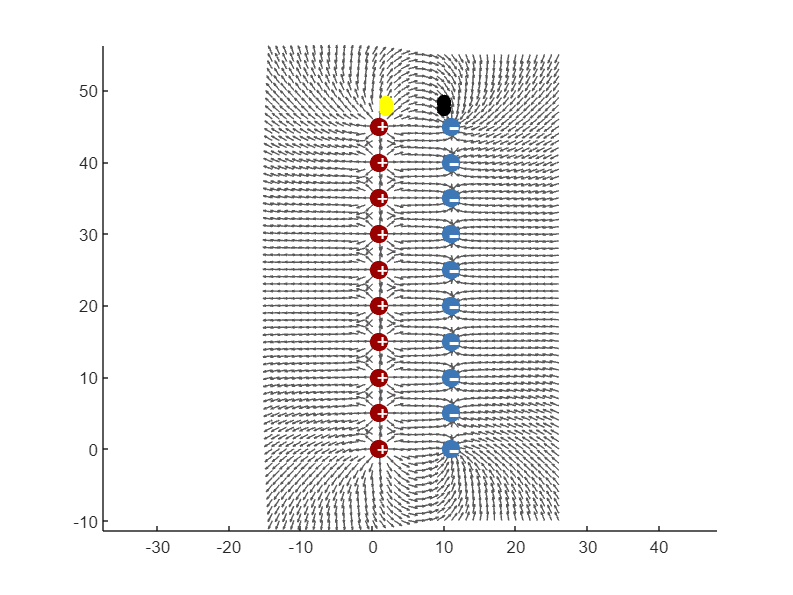

clc; clear; close all;

% Constante de Coulomb
k = 9*10^9;

% Input del número de cargas, las cargas y sus posiciones en el plano cartesiano
numDCargas = input("Número de Cargas: ");

q1 = (input("Valor de la carga: "));
q2 = -1*q1; % q2 es el valor opuesto a q1 

distanciaCP = input("Distancia entre Cargas Positivas: ");
distanciaCN = input("Distancia entre Cargas Negativas: ");

q1_pos = [input("Posición X de la primera carga positiva: "), 0];
d = input("Distancia entre cargas positivas y negativas: ");
q2_pos = [q1_pos(1) + d, (((numDCargas-1)*distanciaCP)/2)-(((numDCargas-1)*distanciaCN)/2)];

% se crea una variable para las posiciones de todas las cargas
posicionesCargasPositivas = q1_pos;
posicionesCargasNegativas = q2_pos;

% Condicional que convierte la variable en una matriz solo si el numero
% de cargas dado es mayor a uno
if numDCargas > 1 

    % Ciclo for que añade las posiciones que faltan para las cargas
    % positivas y negativas a partir de la 3era posición
    for i = 2:numDCargas
        % La línea de cada lado de cargas será en el eje Y, así que se le suma
        % 1 a la carga de la posicion anterior en el componente Y
        % se crea una nueva posicion para las cargas positivas y negativas
        % con el componente en x de la carga anterior y el componente en y
        % de la carga anterior más 1, para hacer la línea vertical. 
        nuevaPosicionP = [posicionesCargasPositivas(end,1), posicionesCargasPositivas(end,2)+distanciaCP];
        posicionesCargasPositivas(end+1,:) = nuevaPosicionP;
        nuevaPosicionN = [posicionesCargasNegativas(end,1), posicionesCargasNegativas(end,2)+distanciaCN];
        posicionesCargasNegativas(end+1,:) = nuevaPosicionN;
    end
end 

% se crean los vectores vacíos que se utilizarán
[x,y,ex,ey,exn,eyn] = deal([]);

% Ciclos for que determina los valores de los vectores del campo eléctrico
% para todos los puntos en el rango de la primera partícula menos la 
% distancia entre ellas hasta la segunda partícula más la distancia.
% El primer for es para el eje X y el segundo para el eje Y. 
for i = q1_pos(1)-(d+((numDCargas)/2)):q2_pos(1)+(d+((numDCargas)/2))
    for j = posicionesCargasPositivas(1,2)-(d):posicionesCargasPositivas(end,2)+(d)
        
        % Posición actual de X y Y
        x(end+1) = i; 
        y(end+1) = j; 
        
        % vectores que se utilizarán para guardar los valores de ambos
        % componentes para cada carga
        componenteCadaCargaX = [];
        componenteCadaCargaY = [];
        
        % Ciclo for que se realiza de 1 a la cantidad de cargas para
        % calcular los componentes en X y Y de la Posición actual respecto
        % a cada una de las cargas
        for ii = 1:numDCargas
           
            % Ecuaciones de los componentes en X respecto a las cargas
            % positivas y negativas
            numP = k*q1*(x(end)-posicionesCargasPositivas(ii,1))/...
            ((((x(end)-posicionesCargasPositivas(ii,1))^2) + ((y(end)-posicionesCargasPositivas(ii,2))^2))^(3/2));
            numN = k*q2*(x(end)-posicionesCargasNegativas(ii,1))/...
            ((((x(end)-posicionesCargasNegativas(ii,1))^2) + ((y(end)-posicionesCargasNegativas(ii,2))^2))^(3/2));
            
            % Se añade al vector de que guarda los componentes en X de cada
            % carga la suma de componentes X de las cargas positiva y
            % negativa en esta posicion
            componenteCadaCargaX(end+1) = ((numP) + (numN)); 
    
            % Ecuaciones de los componentes en Y respecto a las cargas
            % positivas y negativas
            numP = k*q1*(y(end)-posicionesCargasPositivas(ii,2))/...
            ((((x(end)-posicionesCargasPositivas(ii,1))^2) + ((y(end)-posicionesCargasPositivas(ii,2))^2))^(3/2));
            numN = k*q2*(y(end)-posicionesCargasNegativas(ii,2))/...
            ((((x(end)-posicionesCargasNegativas(ii,1))^2) + ((y(end)-posicionesCargasNegativas(ii,2))^2))^(3/2));
            
            % Se añade al vector de que guarda los componentes en Y de cada
            % carga la suma de componentes Y de las cargas positiva y
            % negativa en esta posicion
            componenteCadaCargaY(end+1)= (numP + numN);

        end

        % Se saca el componente en X final del campo eléctrico en este
        % punto sumando todos los componentes en X guardados en el vector
        % ComponenteCadaCargaX
        ex(end+1) = (sum(componenteCadaCargaX));
       
        % Se saca el componente en Y final del campo eléctrico en este
        % punto sumando todos los componentes en Y guardados en el vector
        % ComponenteCadaCargaY
        ey(end+1) = (sum(componenteCadaCargaY));

        % Normalizamos el valor de los componentes dividiendo los
        % componentes entre la magnitud del vector
        vlength = sqrt(((ex(end))^2) + ((ey(end))^2));
        exn(end+1) = ex(end)/vlength;
        eyn(end+1) = ey(end)/vlength;
    end
end


% Plot del campo
axis equal
subplot(1,1,1)

% se activa el hold
hold on
% Se ponen las flechas en el plot con las posiciones de cada punto y
% sus vectores unitarios
quiver(x,y,exn,eyn, "Color", "#5A5A5A") 

% Ciclo for que grafica los puntos de todas las partículas cargadas con su
% respectivo signo
for ii = 1:numDCargas
plot(posicionesCargasPositivas(ii,1), posicionesCargasPositivas(ii,2), color ="#990000", Marker =".", MarkerSize = 32) %Representa el punto 1
text(posicionesCargasPositivas(ii,1)-.4, posicionesCargasPositivas(ii,2),'+','Color','white','FontSize',11);
plot(posicionesCargasNegativas(ii,1),posicionesCargasNegativas(ii,2), color ="#3E77B6", Marker =".", MarkerSize = 32) %Representa el punto 2
text(posicionesCargasNegativas(ii,1)-.4, posicionesCargasNegativas(ii,2)+.3,'-','Color','white','FontSize',18);
end




cargaGlobuloPositivo = 1.6022e-17*100;
cargaGlobuloNegativo= -1.6022e-17*100;

vfx = zeros(1,5);
vfy = zeros(1,5);

x = randperm(5,5)+posicionesCargasPositivas(1,1)+d/2-3;
y = -randi([4, 5],1,5);

vfxb = zeros(1,5);
vfyb = zeros(1,5);

xb = x;
yb = y;


while min(y) < posicionesCargasNegativas(end,2)+d/4 
    %figure(100); %This is so it will replot over the previous figure, and not make a new one.
    globulo = [];
    for ii = 1:1:5
    globulo(end+1) = plot(x(ii),y(ii), color ="k", Marker =".", MarkerSize = 25);
    end

    globulob = [];
    for ii = 1:1:5
    globulob(end+1) = plot(xb(ii),yb(ii), color ="y", Marker =".", MarkerSize = 25, MarkerEdgeColor="y");
    end
    

     for indice = 1:1:5
    

        fuerzasDeCadaCargaX = [];
        fuerzasDeCadaCargaY = [];
        
        % Ciclo for que se realiza de 1 a la cantidad de cargas para
        % calcular los componentes en X y Y de la Posición actual respecto
        % a cada una de las cargas
        for ii = 1:numDCargas
           
            % Ecuaciones de los componentes en X respecto a las cargas
            % positivas y negativas
            numP = k*q1*(x(indice)-posicionesCargasPositivas(ii,1))/...
            ((((x(indice)-posicionesCargasPositivas(ii,1))^2) + ((y(indice)-posicionesCargasPositivas(ii,2))^2))^(3/2));
            numN = k*q2*(x(indice)-posicionesCargasNegativas(ii,1))/...
            ((((x(indice)-posicionesCargasNegativas(ii,1))^2) + ((y(indice)-posicionesCargasNegativas(ii,2))^2))^(3/2));
            
            % Se añade al vector de que guarda los componentes en X de cada
            % carga la suma de componentes X de las cargas positiva y
            % negativa en esta posicion
            fuerzasDeCadaCargaX(end+1) = ((cargaGlobuloPositivo*numP) + (cargaGlobuloPositivo*numN)); 
    
            % Ecuaciones de los componentes en Y respecto a las cargas
            % positivas y negativas
            numP = k*q1*(y(indice)-posicionesCargasPositivas(ii,2))/...
            ((((x(indice)-posicionesCargasPositivas(ii,1))^2) + ((y(indice)-posicionesCargasPositivas(ii,2))^2))^(3/2));
            numN = k*q2*(y(indice)-posicionesCargasNegativas(ii,2))/...
            ((((x(indice)-posicionesCargasNegativas(ii,1))^2) + ((y(indice)-posicionesCargasNegativas(ii,2))^2))^(3/2));
            
            % Se añade al vector de que guarda los componentes en Y de cada
            % carga la suma de componentes Y de las cargas positiva y
            % negativa en esta posicion
            fuerzasDeCadaCargaY(end+1)= (cargaGlobuloPositivo*numP + cargaGlobuloPositivo*numN);

        end

        fuerzaX = sum(fuerzasDeCadaCargaX);
        fuerzaY = sum(fuerzasDeCadaCargaY);
            flength = sqrt(((fuerzaX)^2) + ((fuerzaY^2)));
        fuerzaX = fuerzaX/flength;
        fuerzaY = fuerzaY/flength;
    
        if (x(indice) < posicionesCargasNegativas(1,1))
            ax = fuerzaX/1;
        else
            ax = 0;
        end
        ay = fuerzaY/1;
       
        %vfx = vfx - ax*0.05;
        vfx(indice) = vfx(indice) + ax*0.05;
        vfy(indice) = vfy(indice) + ay*0.05;
        
        %x = x - 0.05;
        if (x(indice) < posicionesCargasNegativas(1,1)-1)
            x(indice) = x(indice) + vfx(indice)*0.05;
        else
            x(indice) = x(indice);
        end
        
        if ((y(indice) < posicionesCargasPositivas(end,2)+d/3) && ((y(indice) > posicionesCargasPositivas(1,2)-d)))
        y(indice) = y(indice) + vfy(indice)*0.05;
        else
            y(indice) = y(indice);
        end
    
     end
     
     % particulas negativas
     for indice = 1:1:5
    

        fuerzasDeCadaCargaX = [];
        fuerzasDeCadaCargaY = [];
        
        % Ciclo for que se realiza de 1 a la cantidad de cargas para
        % calcular los componentes en X y Y de la Posición actual respecto
        % a cada una de las cargas
        for ii = 1:numDCargas
           
            % Ecuaciones de los componentes en X respecto a las cargas
            % positivas y negativas
            numP = k*q2*(xb(indice)-posicionesCargasPositivas(ii,1))/...
            ((((xb(indice)-posicionesCargasPositivas(ii,1))^2) + ((yb(indice)-posicionesCargasPositivas(ii,2))^2))^(3/2));
            numN = k*q1*(xb(indice)-posicionesCargasNegativas(ii,1))/...
            ((((xb(indice)-posicionesCargasNegativas(ii,1))^2) + ((yb(indice)-posicionesCargasNegativas(ii,2))^2))^(3/2));
            
            % Se añade al vector de que guarda los componentes en X de cada
            % carga la suma de componentes X de las cargas positiva y
            % negativa en esta posicion
            fuerzasDeCadaCargaX(end+1) = ((cargaGlobuloPositivo*numP) + (cargaGlobuloPositivo*numN)); 
    
            % Ecuaciones de los componentes en Y respecto a las cargas
            % positivas y negativas
            numP = k*q2*(yb(indice)-posicionesCargasPositivas(ii,2))/...
            ((((xb(indice)-posicionesCargasPositivas(ii,1))^2) + ((yb(indice)-posicionesCargasPositivas(ii,2))^2))^(3/2));
            numN = k*q1*(yb(indice)-posicionesCargasNegativas(ii,2))/...
            ((((xb(indice)-posicionesCargasNegativas(ii,1))^2) + ((yb(indice)-posicionesCargasNegativas(ii,2))^2))^(3/2));
            
            % Se añade al vector de que guarda los componentes en Y de cada
            % carga la suma de componentes Y de las cargas positiva y
            % negativa en esta posicion
            fuerzasDeCadaCargaY(end+1)= (cargaGlobuloPositivo*numP + cargaGlobuloPositivo*numN);

        end

        fuerzaX = sum(fuerzasDeCadaCargaX);
        fuerzaY = sum(fuerzasDeCadaCargaY);
            flength = sqrt(((fuerzaX)^2) + ((fuerzaY^2)));
        fuerzaX = fuerzaX/flength;
        fuerzaY = fuerzaY/flength;
    
        if (xb(indice) > posicionesCargasPositivas(1,1))
            ax = fuerzaX/1;
        else
            ax = 0;
        end
        ay = fuerzaY/1;
       
        %vfx = vfx - ax*0.05;
        vfxb(indice) = vfxb(indice) - ax*0.05;
        vfyb(indice) = vfyb(indice) + ay*0.05;
        
        %x = x - 0.05;
        if (xb(indice) > posicionesCargasPositivas(1,1)+1)
            xb(indice) = xb(indice) - vfxb(indice)*0.05;
        else
            xb(indice) = xb(indice);
        end
        
        if ((yb(indice) < posicionesCargasPositivas(end,2)+d/3) && ((yb(indice) > posicionesCargasPositivas(1,2)-d)))
        yb(indice) = yb(indice) + vfyb(indice)*0.05;
        else
            yb(indice) = yb(indice);
        end
    
     end
    pause(0.1);

    for ii = 1:1:5
    delete(globulo(ii));
    delete(globulob(ii));
    
    end
end

for ii = 1:5
plot(x(ii),y(ii),color ="k", Marker =".", MarkerSize = 25)
plot(xb(ii),yb(ii), color ="y", Marker =".", MarkerSize = 25, MarkerEdgeColor="y");
end

hold off